## Задание 1. Синтез H2-регулятора по состоянию.

Начальные условия полученной мат. модели тележки на задание:

A = [0 1;
     0 0]

A =      0     1
     0     0


B = [0; 1]

B =      0
     1


% C = [1 0;
%      0 0]
C = [1 0;]

C =      1     0


D = [ 0 0]

D =      0     0



Dw = [0 1]

Dw =      0     1


Bw = [0 0 ; 
      1 0]

Bw =      0     0
     1     0


rank(ctrb(A, B))

ans = 2

rank(obsv(A, C))

ans = 2

eig(A)

ans =      0
     0


% x0 = [1 1 1]';
simTimeStart = 0;
simTimeEnd = 10;
step = 0.001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

Выбрать нужно не менее двух значений γ > 0 ...

P.S>>> Оказывается АЧХ для SISO систем можно строить и с помощью функции **sigma**, это частный случай якобы такой:

**`````````**

sigma(___) plots the singular values of the frequency response of sys with default plotting options for all of the previous input argument combinations. If sys is a single-input, single-output (SISO) model, **then the singular value plot is similar to its Bode magnitude response**. For more plot customization options, use sigmaplot.

**`````````**

## **1- Первый набор Cz, Dz**

Cz = [1 0;  
      0 0]; 
Dz = [0;     
      2];    
% Проверка независимости
Cz'*Dz % 0

ans =      0
     0


Bw*Dw' % 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % scalar number

ans = 1

Dz'*Dz % scalar number

ans = 4

Q = Cz' * Cz

Q =      1     0
     0     0


R = Dz' * Dz; R^-1

ans = 0.2500

P = are(A, 1*B*R^-1 *B', Q)

P =     2.0000    2.0000
    2.0000    4.0000


K = -inv(R) * B' * P

K =    -0.5000   -1.0000


EIG_K =  eig(A + B * K) 

EIG_K =   -0.5000 + 0.5000i
  -0.5000 - 0.5000i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### **Рандомное возмущение**

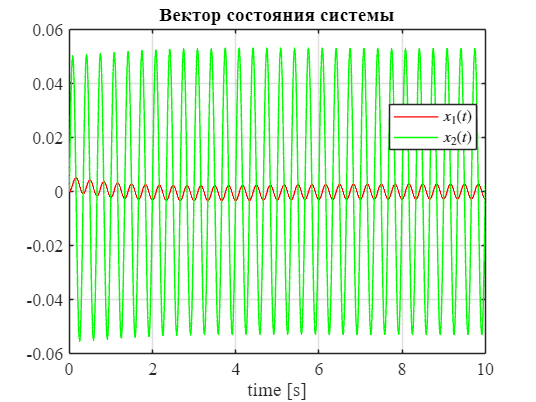

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 3.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("x1");

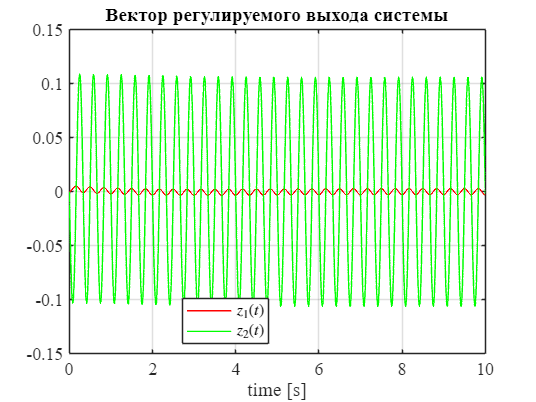


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z1");

### **Близкое к "наихудшему" возмущение, придумали на основе АЧХ-сингулярных числах**

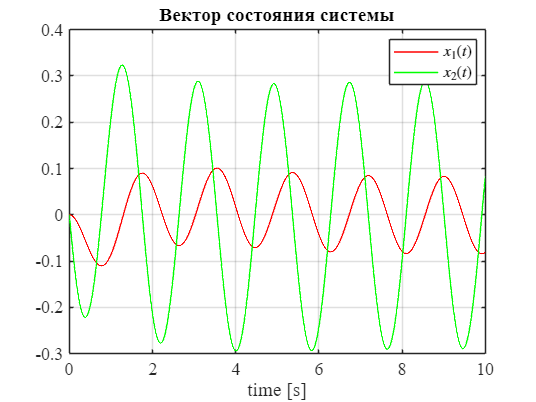

% y = ampl * sin(w*t + phi) %
ampl = 1;
phi = 7*pi/2;
f = 0.55;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("x2");

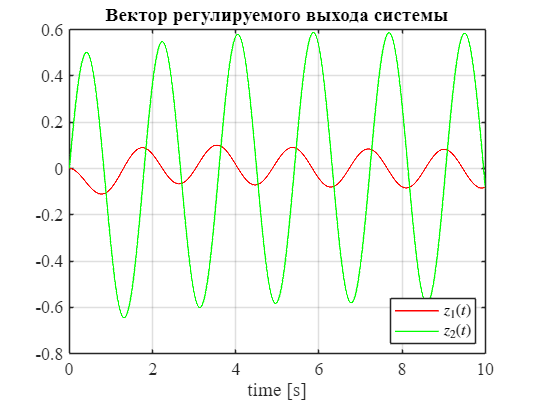


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z2");

Создаём передаточную функцию системы...

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
             1
   1:  -------------
       s^2 + s + 0.5
 
         -2 s^3 - 3 s^2 - 2 s - 0.5
   2:  ------------------------------
       s^4 + 2 s^3 + 2 s^2 + s + 0.25
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


disp(tf2latex(sys));

\begin{bmatrix}\frac{1}{1s^{2} + 1s + 0.5} & 0 \\\\ \frac{-2s^{3} - 3s^{2} - 2s - 0.5}{1s^{4} + 2s^{3} + 2s^{2} + 1s + 0.25} & 0\end{bmatrix}


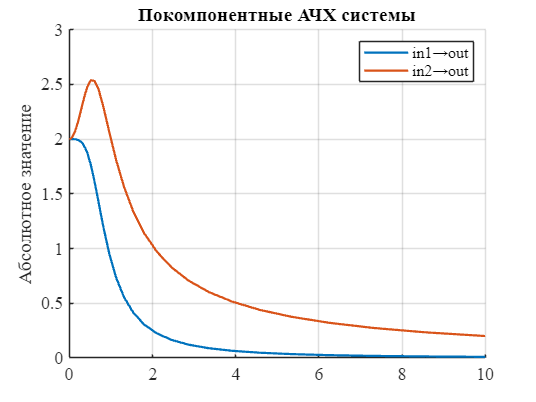

tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

% freqs = linspace(0.00001, 2, 7000);
% omega = 2*pi*freqs;
% Вместо этих двух строчек выше проще в итоге так делать `{0.001,10}`

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components1");

% % Альтернативный способ - применяем sigma к SISO...
% 
% [sv, w] = sigma(sys(1,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
% sv = squeeze(sv);        
% 
% % Строим график
% figure;
% plot(w, sv, 'g', 'LineWidth', 1.5);  
% title('Покомпонентные АЧХ системы - дубликат');
% xlabel('Частота (рад/с)');
% ylabel('Абсолютное значение');
% grid on;
% hold on;
% [sv, w] = sigma(sys(2,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
% sv = squeeze(sv);     
% plot(w, sv, 'r', 'LineWidth', 1.5);  

%%% ЛАЧХ-ЛФЧХ %%% - Вроде не пригодился, наглядности я там не увидел
% freqs = linspace(0.001, 10, 5000);
% omega = 1*freqs; %2*pi*freqs;
% [mag, ~, wout] = bode(sys(1,1), {0.001, 10}); % omega is in rad/s
% mag = squeeze(mag); % Magnitude (absolute, not dB)
% phase = squeeze(phase); % Phase (degrees)
% 
% figure;
% loglog(wout, mag, 'b', 'LineWidth', 1.5);
% xlabel('Frequency (Hz)');
% ylabel('Magnitude (abs)');
% title(' ');
% grid on; hold on;
% legend('sim', 'Location', 'best')

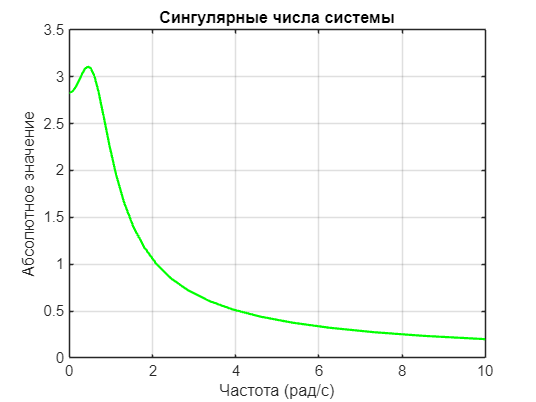

% !!! sys(:,1) instead of sys
[sv, wout] = sigma(sys(:,1), {0.001,10});
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values1");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 2

H_inf_norm = norm(sys, inf)

H_inf_norm = 3.1075

## **2 - Второй набор Cz, Dz**

Cz = [1 5;  
      0 0]; 
Dz = [0;     
      2];      
% Проверка независимости
Cz'*Dz % 0

ans =      0
     0


Bw*Dw' % 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % scalar number

ans = 1

Dz'*Dz % scalar number

ans = 4

Q = Cz' * Cz

Q =      1     5
     5    25


R = Dz' * Dz

R = 4

P = are(A, 1*B*R^-1 *B', Q)

P =     0.3852    2.0000
    2.0000   10.7703


K = -inv(R) * B' * P

K =    -0.5000   -2.6926


EIG_K =  eig(A + B * K) 

EIG_K =    -0.2006
   -2.4919


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### **Рандомное возмущение**

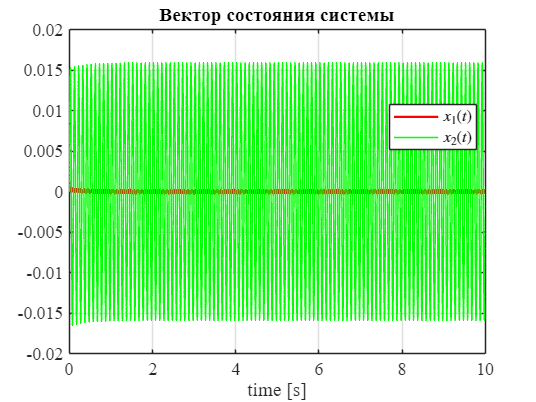

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = pi/2;
f = 10.0;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x(:,1), 'r', 'LineWidth', 1.5); hold on
plot(time, x(:,2), 'g-', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("x3");

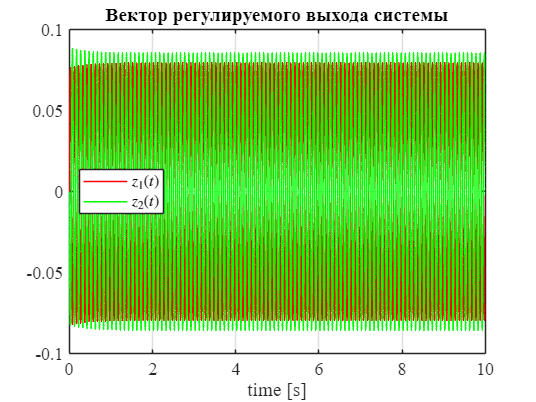


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z3");

### **Близкое к "наихудшему" возмущению, на основе АЧХ-сингулярных числах**

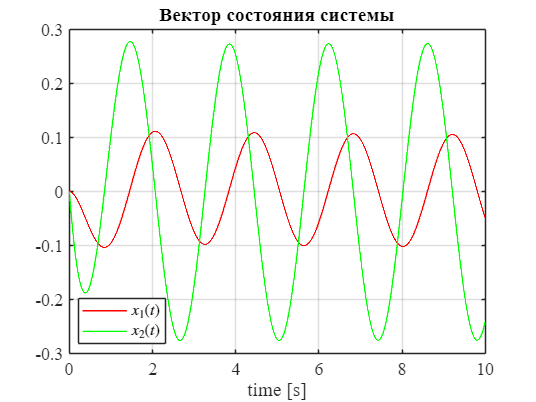

% y = ampl * sin(w*t + phi)
ampl = 1;
phi = 7*pi/2;
f = 0.42;
w = 2*pi * f;

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.x_plant.Time;                
x = out.x_plant.Data;
y = out.y_plant.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("x4");

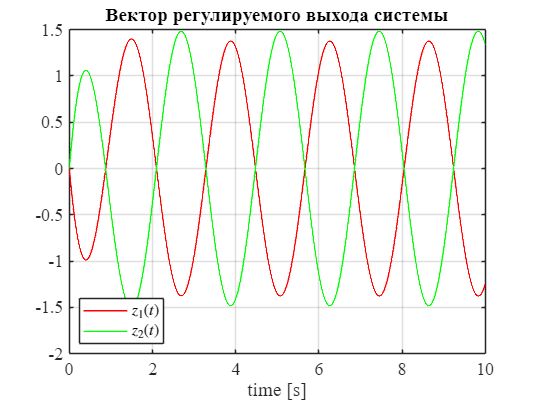


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z4");

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
            5 s^3 + 14.46 s^2 + 5.193 s + 0.5
   1:  -------------------------------------------
       s^4 + 5.385 s^3 + 8.25 s^2 + 2.693 s + 0.25
 
          -5.385 s^3 - 15.5 s^2 - 5.385 s - 0.5
   2:  -------------------------------------------
       s^4 + 5.385 s^3 + 8.25 s^2 + 2.693 s + 0.25
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.


disp(tf2latex(sys));

\begin{bmatrix}\frac{5s^{3} + 14.46s^{2} + 5.19s + 0.5}{1s^{4} + 5.39s^{3} + 8.25s^{2} + 2.69s + 0.25} & 0 \\\\ \frac{-5.39s^{3} - 15.5s^{2} - 5.39s - 0.5}{1s^{4} + 5.39s^{3} + 8.25s^{2} + 2.69s + 0.25} & 0\end{bmatrix}


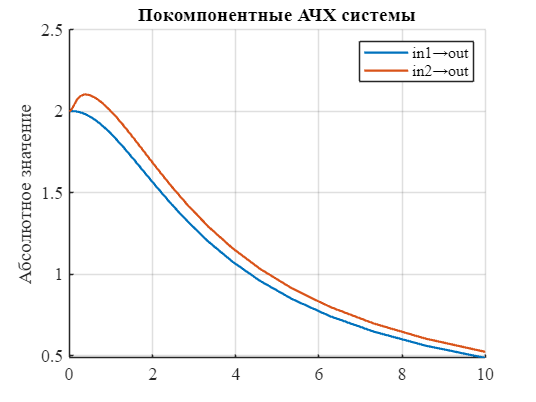

tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components2");

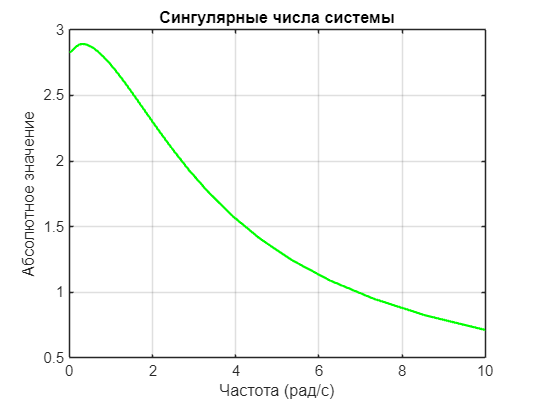

% !!! sys(:,1) instead of sys
[sv, wout] = sigma(sys(:,1), {0.001,10});  
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values2");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 3.2818

H_inf_norm = norm(sys, inf)

H_inf_norm = 2.8914

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab11\latex11\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end